# Q3 - Variable Ordering

load('hw5_A.mat'); %produces A matrix in the workspace

## (a) Obtain R with QR fatorization

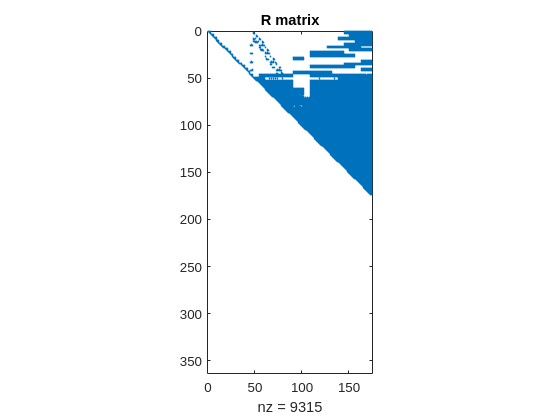

[~,R] = qr(A);
spy(R);
title('R matrix');

## (b) best R

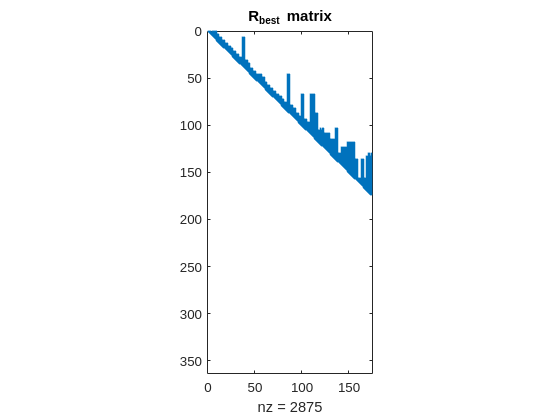

p = colamd(A);
[~,Rbest] = qr(A(:,p));
spy(Rbest);
title('R_{best} matrix');

$R_{\mathrm{best}}$ has ~30% values of the initial $R$ matrix.

Hence will require to do only ~30% of the computations when sovling back subsitution with $R_{\mathrm{best}}$ when compared to $R$.